# Qiita API でデータ抽出

Copyright (c) 2020-2023, The MathWorks, Inc.

[![View Qiita API を使った Qiita 投稿解析例  on File Exchange](https://www.mathworks.com/matlabcentral/images/matlab-file-exchange.svg)](https://jp.mathworks.com/matlabcentral/fileexchange/75099-qiita-api-qiita)

Qiita は Qiita API を公開しており、様々なデータ抽出を可能にしてくれています。ここでは MATLAB / Simulink タグの投稿状況を見てみます。

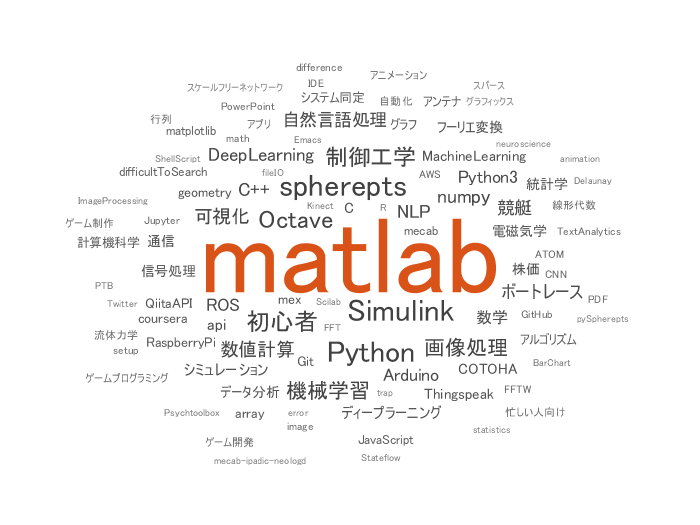

## 記事データ取得

matlab タグ、simulink タグがついた全記事を取得します。ご自身の accessToken を取得してお試しください。

clear
loadFlag = false;

if loadFlag || ~exist('allArticles.mat','file')
    % アクセストークン使用（ご自身の accessToken を取得してお試しください）
    accessToken = 'Bearer xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx';
    opts = weboptions('HeaderFields',{'Authorization',accessToken});
    % opts = weboptions; % アクセストークン使用しない場合
    
    page = 1;
    data = [];
    tags = ["matlab","simulink"];
    for ii=1:2 % 2つの tag をループで処理
        page = 1;
        while true
            % 1 request 辺りの上限が 100 件なので繰り返し処理
            url = "https://qiita.com/api/v2/tags/" + tags(ii) + "/items?page="+page+"&per_page=100";
            tmp = webread(url,opts);
            if isempty(tmp)
                break;
            end
            data = [data;tmp]; %#ok<AGROW>
            page = page + 1;
        end
    end
    % テーブル型に変更
    data = struct2table(data);
    
    % 念のため unique で重複回避
    [~,ia,~] = unique(data.id);
    data = data(ia,:);
    save('allArticles.mat','data')
else
    load allArticles.mat %#ok<UNRCH>
end

## データ確認

冒頭の8アイテムを表示してみます。変数として `title`、`rendered_body` や `created_at`、`like_count` など全16変数が取れていることが分かります。 (rendered_body と body はアレなので削除して表示します。)

head(removevars(data,{'rendered_body','body'}))

    coediting    comments_count             created_at                 group                   id               likes_count    private    reactions_count    stocks_count        tags                                  title                                       updated_at                                            url                                      user       page_views_count    team_membership    organization_url_name
    _________    ______________    _____________________________    ____________    ________________________    ___________    _______    _______________    ____________    ____________    _________________________________________________________    _____________________________    ________________________________________________________________    __________    ________________    _______________    _____________________

      false            0           {'2018-05-05T23:01:26+09:00'}    {0×0 double}    {'009a739099fbd50e09ef'}         3          false            0 

## 時系列データ集計

投稿数の推移を集計するために `timetable` 型を活用します。

作成日時 `created_at` は `datetime` 型にします。フォーマットに注目。

created_at = datetime(vertcat(data.created_at),...
    'InputFormat', "uuuu-MM-dd'T'HH:mm:ss'+09:00");
tData = table2timetable(data(:,{'title','user','likes_count','tags','url'}),'RowTimes', created_at);

ここではタイトル、ユーザー名、いいね数、タグ、Page URL だけを残しておきます。`url` はセルの中に `char` で入っている状態なので簡単ですが、`user` はセルに入った構造体 `tag` はセルに入った構造体ベクトルなので少しややこしい。

具体的にはこんな感じ・・

tData.user(1)

ans = フィールドをもつ struct :
            description: '大学時代はC言語でポインターを駆使して画像処理、時系列データ解析を行い、SIerでシステム設計、ソフトウェア開発(主にJavaScriptのフロントエンド)を行い、現在は外資系IT企業でエンジニアをやっています。HTML/JavaScript、PHP、Java、.NET、MATLAB、SQLなどなど、色々なプログラム言語を使うので、言語の違いを楽しみながら日々バリバリ書いています。'
            facebook_id: ''
        followees_count: 3
        followers_count: 9
      github_login_name: []
                     id: 'Alberobellojiro'
            items_count: 4
            linkedin_id: ''
               location: ''
                   name: ''
           organization: ''
           permanent_id: 254990
      profile_image_url: 'https://qiita-image-store.s3.amazonaws.com/0/254990/profile-images/1525506429'
              team_only: 0
    twitter_screen_name: []
            website_url: ''


tData.tags{1}

ans = フィールドをもつ 2×1 の struct 配列:
    name
    versions


ここでは `timetable` 型の各行に関数を適用する `rowfun` 関数を使ってみます。`tags` については構造体の `name` メンバーだけを `string` 型のベクトルに変換。諦めて for ループで回した方が可読性がよいかもしれませんね。

tData.url = string(tData.url);
tData.user = rowfun(@(x) string(x.id),tData,'InputVariable','user','ExtractCellContents',true,'OutputFormat','uniform');
tData.tags = rowfun(@(x) string({x.name}),tData,'InputVariable','tags','ExtractCellContents',true,'SeparateInputs',true,'OutputFormat','cell');

結果こんな感じです。ついでに時系列順に並べておきましょう。

tData = sortrows(tData,'Time','descend');
head(tData)

           Time                                                title                                            user         likes_count                                       tags                                                                  url                            
    ___________________    _____________________________________________________________________________    _____________    ___________    __________________________________________________________________________    __________________________________________________________

    2023/03/20 15:50:23    {'データに基づくプラントモデリングおよびコントローラー開発'                           }    "getBack1969"         2         {["MATLAB"    "制御工学"    "Simulink"    "モデル予測制御"    "システム同定"  ]}     "https://qiita.com/getBack1969/items/f01a105e2b4ac3b424b6"
    2023/03/20 08:34:26    {'ChatGPTでSimulinkモデルを作ってみた'                                         }    "covao"               4         {["MATLAB"    "Simulink"    "ChatGPT"    "ChatGPTPlus"    "GPT-

## ワードクラウド

どんなタグがあるのかワードクラウド表示してみます。

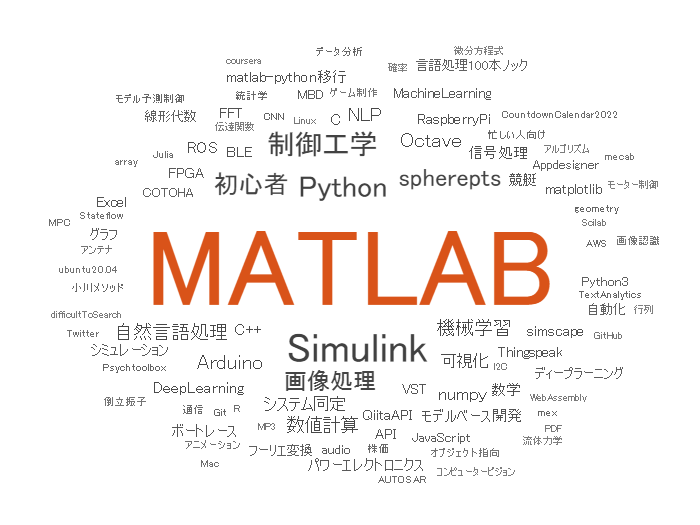

alltags = [tData.tags{:}];
[N,Categories] = histcounts(categorical(alltags));
wordcloud(Categories,N)

## 月間投稿数推移

月間投稿数を集計してみます。ここは `retime` の出番です。

と、新しい時間ステップ `newTimeStep` と集計方法 `method` を指定します。月間投稿数であれば

tmp = retime(tData(:,'title'),'monthly','count');

棒グラフ表示しますと、2019 年後半から急増していることは分かりますね。2019年12月のピークはアドベントカレンダーの影響です。

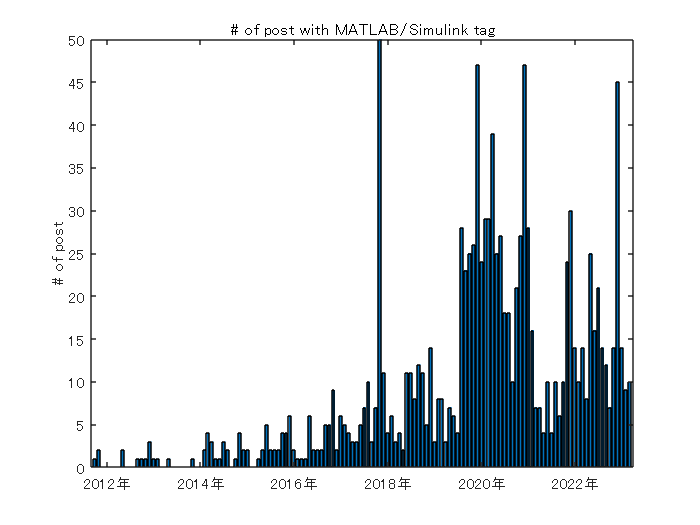

bar(tmp.Time,tmp.title)
title('# of post with MATLAB/Simulink tag')
ylabel('# of post')

## いいね（LGTM）数の推移

### 中央値

ここも `retime` の出番です。ただ今回は外れ値（バズった記事の影響を鑑みて）中央値を見てみます。集計方法 `method` を `median` にします。集計期間は四半期 `quarterly` で。

tmp = retime(tData(:,'likes_count'),'quarterly',@median);

棒グラフ表示しますと・・特に増えているわけではないですね。。

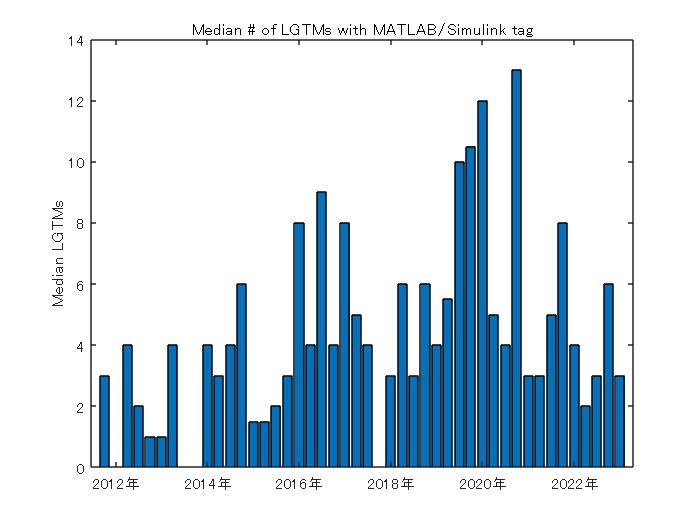

bar(tmp.Time,tmp.likes_count)
title('Median # of LGTMs with MATLAB/Simulink tag')
ylabel('Median LGTMs')

### 平均値（トリム平均）

外れ値に対して強い平均値としては上位・下位ｘ％を除外して平均値をとるトリム平均もあります。Statistics and Machine Learning Toolbox の `trimmean` が便利。今度は年間集計ということで 'yearly' とします。`trimmean` では上位・下位5％づつ削除した平均値とします。 

if license('checkout','Statistics_Toolbox')
    tmp = retime(tData(:,'likes_count'),'yearly',@(x) trimmean(x, 10));

棒グラフ表示します。これだと増えているように見えますね。

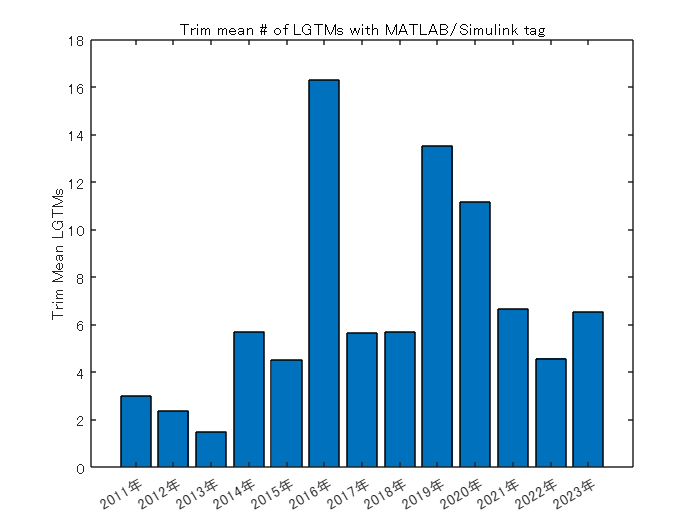

    bar(tmp.Time,tmp.likes_count)
    title('Trim mean # of LGTMs with MATLAB/Simulink tag')
    ylabel('Trim Mean LGTMs')
end

## OnThisDay

過去の「この日」に投稿された記事・・という順に並べてみます。たとえば過去の投稿をなつかしんだり。。

まず `ymd` 関数で日付を年、月、日に分解します。

% get the month/day of when the post is created
[y,m,d] = ymd(tData.Time);

そして年数を引く・・と

daysofYear = tData.Time - years(y);
[tData.Time(1), daysofYear(1)]

ans = 1×2 の datetime 配列
   2023/03/20 15:50:23   0000/03/20 01:58:47


うまくいきません。年によって実際の長さが違うから・・だと思います。年数だけ引く場合は `calyears` を使います。

daysofYear = tData.Time - calyears(y);
[tData.Time(1), daysofYear(1)]

ans = 1×2 の datetime 配列
   2023/03/20 15:50:23   0000/03/20 15:50:23


キッチリ年数分引けていますね。ということで、記事の年齢（何年前に投稿された記事か）をデータに加えて、1月から順に並べておきます。

% How old the posts are
tData.howOld = 2020 - y;
% sort by the days of the year
[~,idx] = sort(daysofYear,'ascend');
tData = tData(idx,:);
head(tData)

           Time                                           title                                         user           likes_count                          tags                                                        url                                  howOld
    ___________________    ___________________________________________________________________    _________________    ___________    _________________________________________________    ______________________________________________________________    ______

    2017/01/01 16:17:02    {'MATLAB2015b(32bit版)でpointgrayのサポートパッケージが動かない話'      }    "nomper"                  0         {["MATLAB"    "camera"    "pointgray"    "imaq"]}    "https://qiita.com/nomper/items/45e47434f746d852acd4"                3  
    2023/01/02 08:53:25    {'忙しい MATLAB 芸人向け Qiita ふり返り（2022 年版）'                  }    "eigs"                   11         {["MATLAB"    "QiitaAPI"    "忙しい人向け"       ]}     "https://qiita.com/eigs/items/e74c6caf408bb891a93b"      

## 投稿された曜日

曜日については

の構文でとれます。

tData.dayofWeek = day(tData.Time,'name');

曜日別に投稿数を確認してみます。

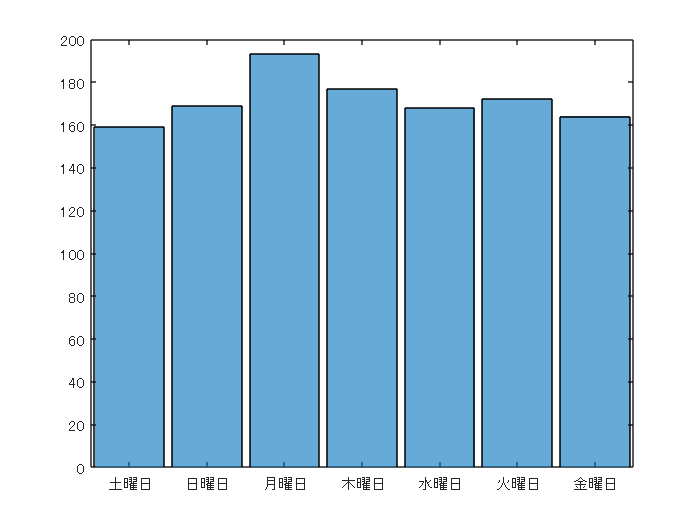

histogram(categorical(tData.dayofWeek));

あんまり差がないですね。一応月曜日が一番多いですね。

表示がアルファベット順なので修正。

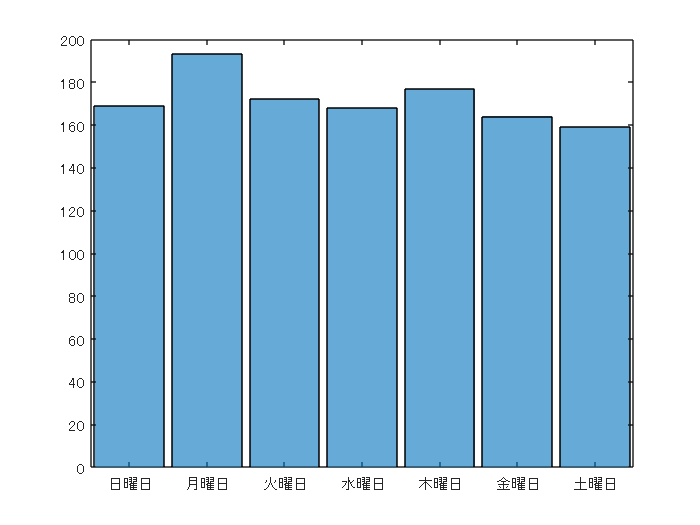

histogram(categorical(tData.dayofWeek),["日曜日","月曜日","火曜日","水曜日","木曜日","金曜日","土曜日"]);